# **RRA**

# **LAB 2 (Parteneriat cu laburile scrise de PETrascu)**

## **Rang normal si Operatii cu Sisteme**

### **1) Rang Normal**

Fie o realizare $G\left(s\right)=\left\lbrack \begin{array}{cc}
A & B\\
C & D
\end{array}\right\rbrack$, nu neaparat minimala. Definim **rangul normal** al lui $G\left(s\right)\;\mathrm{si}\;{\mathrm{sE}}_z -A_z \;\left(\mathrm{fascicul}\;\mathrm{de}\;\mathrm{zerouri}\;\mathrm{al}\;\mathrm{lui}\;H\right)$ in acest fel: ${\textrm{rang}}_n G\left(s\right)={\textrm{rang}}_n \left({\textrm{sE}}_z -A_z \right)-n$.

**Haide sa vedem si de ce:**

Mai intai sa ne aducem aminte cine este ${\textrm{sE}}_z -A_z =\left\lbrack \begin{array}{cc}
A-\textrm{sI} & B\\
C & D
\end{array}\right\rbrack$


$${\textrm{rang}}_n \left({\textrm{sE}}_z -A_z \right)={\textrm{rang}}_n \left\lbrack \begin{array}{cc}
I & 0\\
{C\left(\textrm{sI}-A\right)}^{-1}  & I
\end{array}\right\rbrack *\left\lbrack \begin{array}{cc}
A-\textrm{sI} & B\\
C & D
\end{array}\right\rbrack *\left\lbrack \begin{array}{cc}
I & {\left(\textrm{sI}-A\right)}^{-1} B\\
0 & I
\end{array}\right\rbrack =$$



$${\textrm{rang}}_n \left\lbrack \begin{array}{cc}
A-\textrm{sI} & B\\
0 & {C\left(\textrm{sI}-A\right)}^{-1} B+D
\end{array}\right\rbrack *\left\lbrack \begin{array}{cc}
I & {\left(\textrm{sI}-A\right)}^{-1} B\\
0 & I
\end{array}\right\rbrack =$$


${\textrm{rang}}_n \left\lbrack \begin{array}{cc}
A-\textrm{sI} & 0\\
0 & {C\left(\textrm{sI}-A\right)}^{-1} B+D
\end{array}\right\rbrack ={\textrm{rang}}_n \left\lbrack \begin{array}{cc}
A-\textrm{sI} & 0\\
0 & G\left(s\right)
\end{array}\right\rbrack$. Practic am facut matrice diagonala de unde scot usor rangul ei, si anume ${\textrm{rang}}_n \left\lbrack \begin{array}{cc}
A-\textrm{sI} & 0\\
0 & G\left(s\right)
\end{array}\right\rbrack ={\textrm{rang}}_n \;G\left(s\right)+{\textrm{rang}}_n \;\left(A-\textrm{sI}\right)={\textrm{rang}}_n \;G\left(s\right)+n,\textrm{pentru}\;\forall$ realizare

### Complement Schur

Fie matricea $M=\left\lbrack \begin{array}{cc}
M_{11}  & M_{12} \\
M_{21}  & M_{22} 
\end{array}\right\rbrack$. Definim $M/M_{22} =M_{11} -M_{12} M_{22}^{-1} M_{21}$ si se numeste complement Schur al lui $M$ in raport cu $M_{22}$

$M/M_{11} =M_{22} -M_{21} M_{11}^{-1} M_{12}$ si se numeste complement Schur al lui $M$ in raport cu $M_{11}$

In acest sens, $\textrm{rang}\;M=\left\lbrace \begin{array}{l}
\textrm{rang}\;M_{11} +\textrm{rang}\;M/M_{11} \\
\textrm{rang}\;M_{22} +\textrm{rang}\;M/M_{22} 
\end{array}\right.$

### 2) Operatii cu sisteme

- ***Dualizarea***: $G\left(s\right)\to G^T \left(s\right)\Rightarrow \left\lbrack \begin{array}{cc}
A & B\\
C & D
\end{array}\right\rbrack \to \left\lbrack \begin{array}{cc}
A^T  & C^T \\
B^T  & D^T 
\end{array}\right\rbrack$. **Dualul este bine definit pentyru orice sistem**

- ***Inversarea:*** $G\left(s\right)\to G^{-1} \left(s\right)$. Fie un sistem $y=\textrm{Gu}$. Daca **numarul de intrati = numarul de iesiri** si **G este inversabila ca matrice rationala**, atunci se definteste **inversul** acestui sistem prin i**nterschimbarea intrarilor si iesirilor (practic polii si zerourile fac switch).** Daca in plus D este inversabil, atunci o realizare de stare este $G^{-1} \left(s\right)=\left\lbrack \begin{array}{cc}
A-{\textrm{BD}}^{-1} C & {\textrm{BD}}^{-1} \\
-D^{-1} C & D^{-1} 
\end{array}\right\rbrack$. Daca doamne fereste $D^{-1}$ **nu **$\exists$, **nu** pot scrie pe $G\left(s\right)$ in **spatiul starilor (state-space)**

- ***Conjugarea:*** $G\left(s\right)\to \left\lbrace \begin{array}{l}
G^T \left(-s\right)=G^{\tilde{} } \left(s\right)\;\textrm{pentru}\;\textrm{coeficienti}\;\mathbb{R}\\
\bar{G^T \left(\bar{-s} \right)} =G^{\tilde{} } \left(s\right)\;\textrm{pentru}\;\textrm{coeficienti}\;\mathbb{C}
\end{array}\right.$

- ***Conexiune serie:*** fie 2 sisteme $\left\lbrace \begin{array}{ll}
y_1 =G_1 u_1  & G_1 =\left\lbrack \begin{array}{cc}
A_1  & B_1 \\
C_1  & D_1 
\end{array}\right\rbrack \\
y_2 =G_2 u_2  & G_2 =\left\lbrack \begin{array}{cc}
A_2  & B_2 \\
C_2  & D_2 
\end{array}\right\rbrack 
\end{array}\right.$, Daca $m_{G_1 } =p_{G_2 }$, adica numarul de intari din $G_1$ = numarul de iesiri din $G_2$, atunci conexiunea serie a lui $G_1 \;\textrm{cu}\;G_2$ este sistemul cu $\left\lbrace \begin{array}{l}
u:=u_1 \\
y:=y_2 \\
u_2 =y_1 
\end{array}\right.$. In acest sens, conexunea serie este bine definita si matricea de transfer a sistemului este $G\left(s\right)=G_1 \left(s\right)G_2 \left(s\right)=\left\lbrack \begin{array}{ccc}
A_2  & B_2 C_1  & B_2 D_1 \\
0 & A_1  & B_1 \\
C_2  & D_2 C_1  & D_2 D_1 
\end{array}\right\rbrack$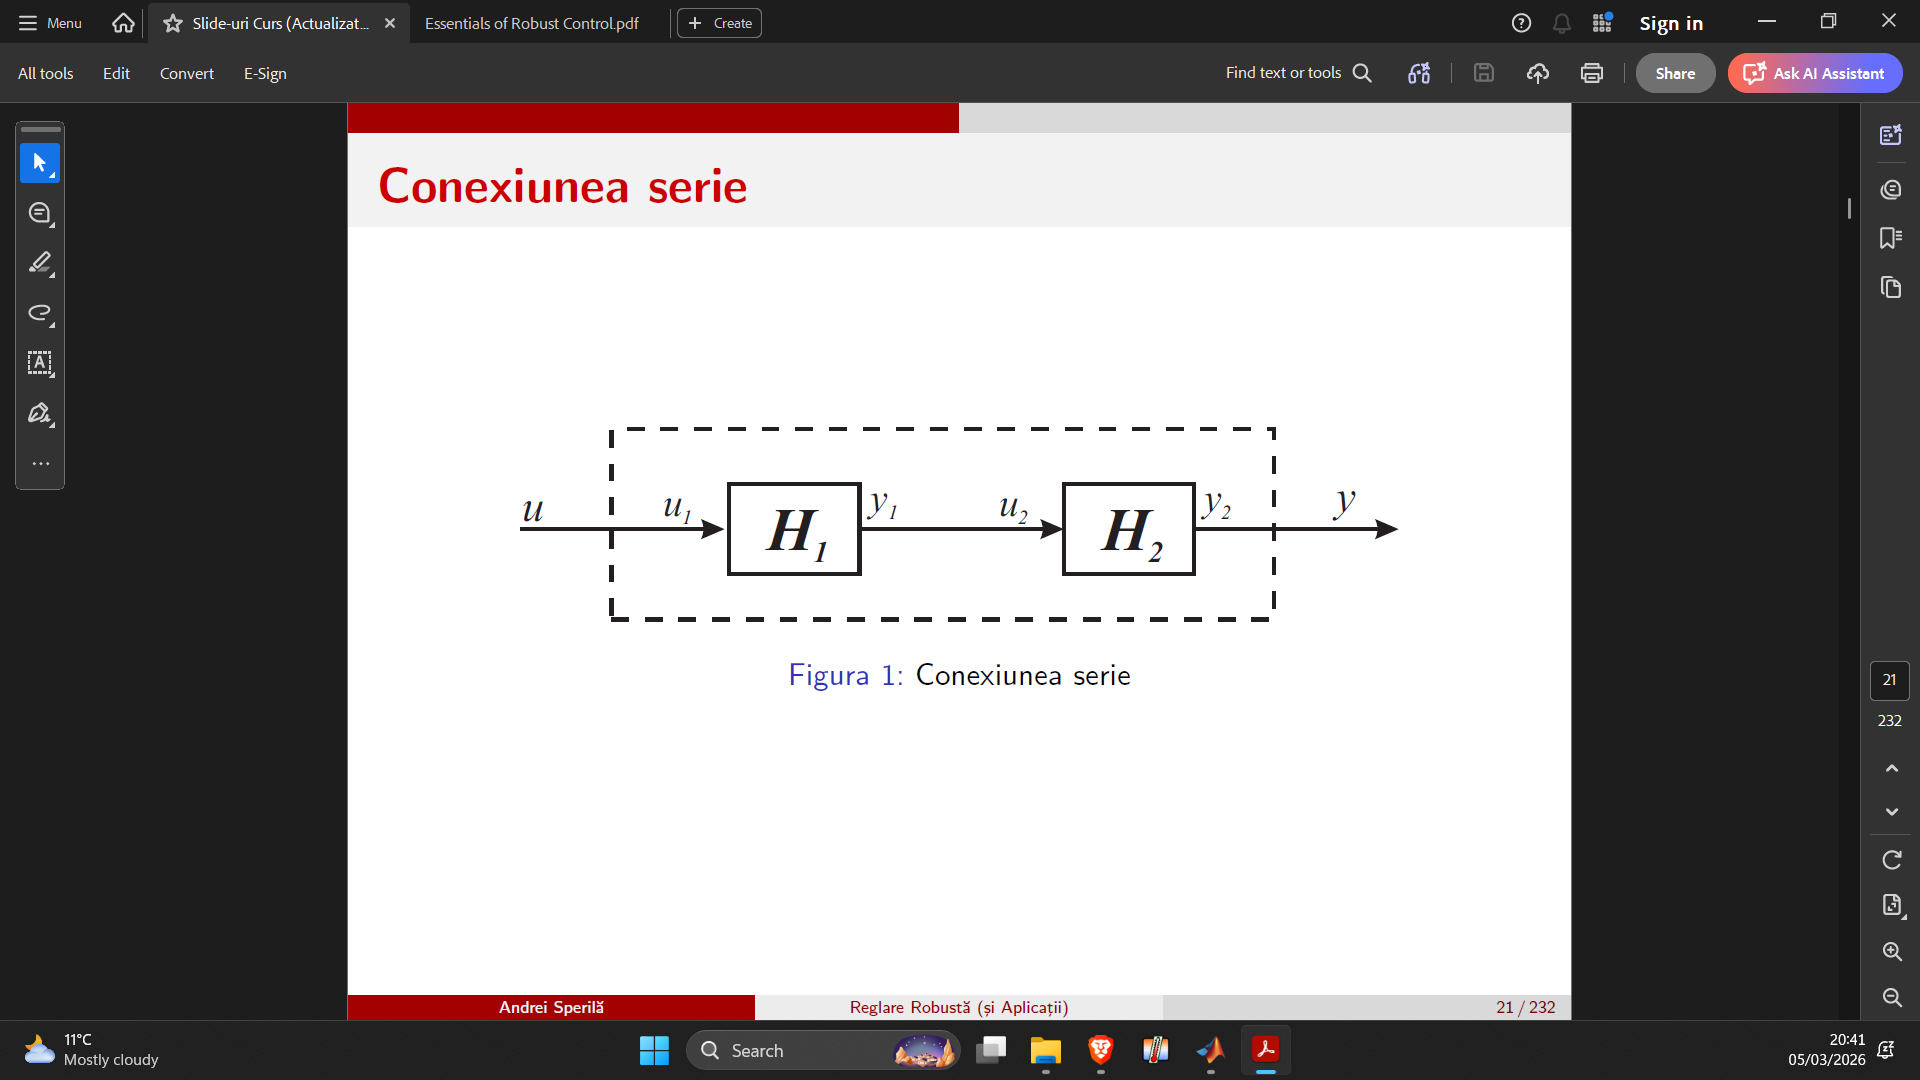

- ***Conexiune paralel:*** Fie 2 sisteme $\left\lbrace \begin{array}{ll}
y_1 =G_1 u_1  & G_1 =\left\lbrack \begin{array}{cc}
A_1  & B_1 \\
C_1  & D_1 
\end{array}\right\rbrack \\
y_2 =G_2 u_2  & G_2 =\left\lbrack \begin{array}{cc}
A_2  & B_2 \\
C_2  & D_2 
\end{array}\right\rbrack 
\end{array}\right.$. Daca aceste sisteme au **acelasi numar de intrari** si respectiv** acelasi numar de iesiri**, atunci se defineste conexiunea paralel a lui $G_1 \;\textrm{cu}\;G_2$ ca fiins sistemul care are intrarea u obtinuta punand $\left\lbrace \begin{array}{l}
u:=u_1 =u_2 \\
y:=y_1 +y_2 
\end{array}\right.$. In acest sens, conexiunea paralel este bine definita, iar matricea de transfer a sistemului este: $G\left(s\right)=G_1 \left(s\right)+G_2 \left(s\right)=\left\lbrack \begin{array}{ccc}
A_1  & 0 & B_1 \\
0 & A_2  & B_2 \\
C_1  & C_2  & D_1 +D_2 
\end{array}\right\rbrack$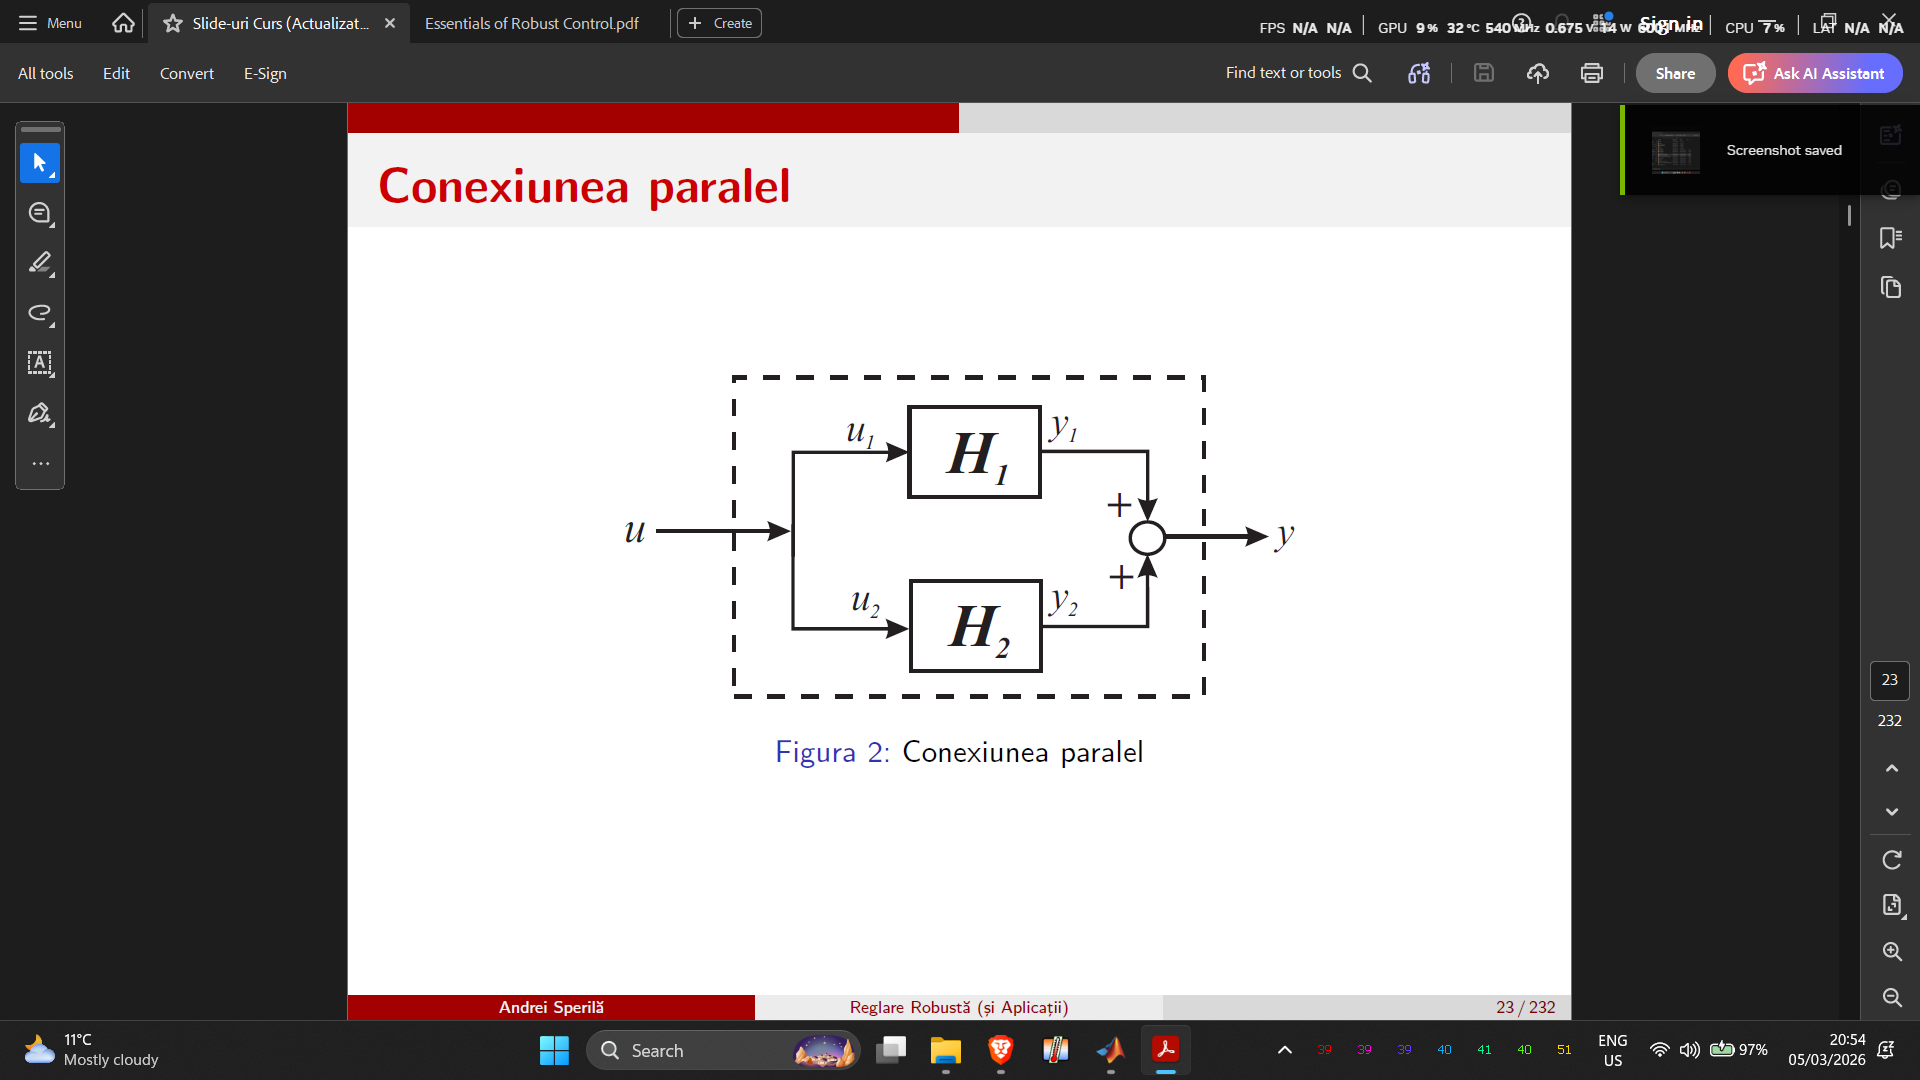

- ***Conexiune in bucla de reactie:*** Fie 2 sisteme $\left\lbrace \begin{array}{ll}
y_1 =G_1 u_1  & G_1 =\left\lbrack \begin{array}{cc}
A_1  & B_1 \\
C_1  & D_1 
\end{array}\right\rbrack \\
y_2 =G_2 u_2  & G_2 =\left\lbrack \begin{array}{cc}
A_2  & B_2 \\
C_2  & D_2 
\end{array}\right\rbrack 
\end{array}\right.$. Daca **numarul de iesiri a lui **$G_1$ = **numarul de intrari al lui **$G_2$ si **numarul de iesiri a lui **$G_2$ = **numarul de intrari al lui **$G_1$, atunci se defineste conexiunea in bucla de reactie a lui $G_1 \;\textrm{cu}\;G_2$ ca fiind sistemul ce are $\left\lbrace \begin{array}{l}
\textrm{intrarile}\;w_1 \;\textrm{si}\;w_2 \\
\textrm{iesirile}\;y_1 \;\textrm{si}\;y_2 
\end{array}\right.$, punand $\left\lbrace \begin{array}{l}
u_1 =w_1 +y_2 \\
u_2 =y_2 +y_1 
\end{array}\right.$. In acest sens, conexiunea in bucla de reactie este bine definita $\Leftrightarrow \left\lbrack \begin{array}{cc}
I & -D_2 \\
-D_1  & I
\end{array}\right\rbrack$este inversabila, sau echivalent $\Leftrightarrow \left\lbrace \begin{array}{l}
I-D_2 D_1 \;\textrm{inversabila}\\
I-D_1 D_2 \;\textrm{inversabila}
\end{array}\right.$. Sa folosim in acest caz Complement Schur: $\textrm{rang}\left\lbrack \begin{array}{cc}
I_{\textrm{p1}}  & -D_1 \\
-D_2  & I_{\textrm{p2}} 
\end{array}\right\rbrack =p_1 +p_2 \Leftrightarrow \left\lbrace \begin{array}{l}
p_1 +\textrm{rang}\left(I-D_2 D_1 \right)=p_1 +p_2 \\
p_2 +\textrm{rang}\left(I-D_1 D_2 \right)=p_1 +p_2 
\end{array}\right.$$\Leftrightarrow \left\lbrace \begin{array}{l}
\textrm{rang}\left(I-D_2 D_1 \right)=p_2 \\
\textrm{rang}\left(I-D_1 D_2 \right)=p_1 
\end{array}\right.$. Daca $\left\lbrack \begin{array}{cc}
I & -D_2 \\
-D_1  & I
\end{array}\right\rbrack$nu este inversabila, atunci **nu avem formula pentru bucla pe stare**, deci **improprie** si poate fi scrisa pe descriptori $\left(A,B,C,D,E\right)$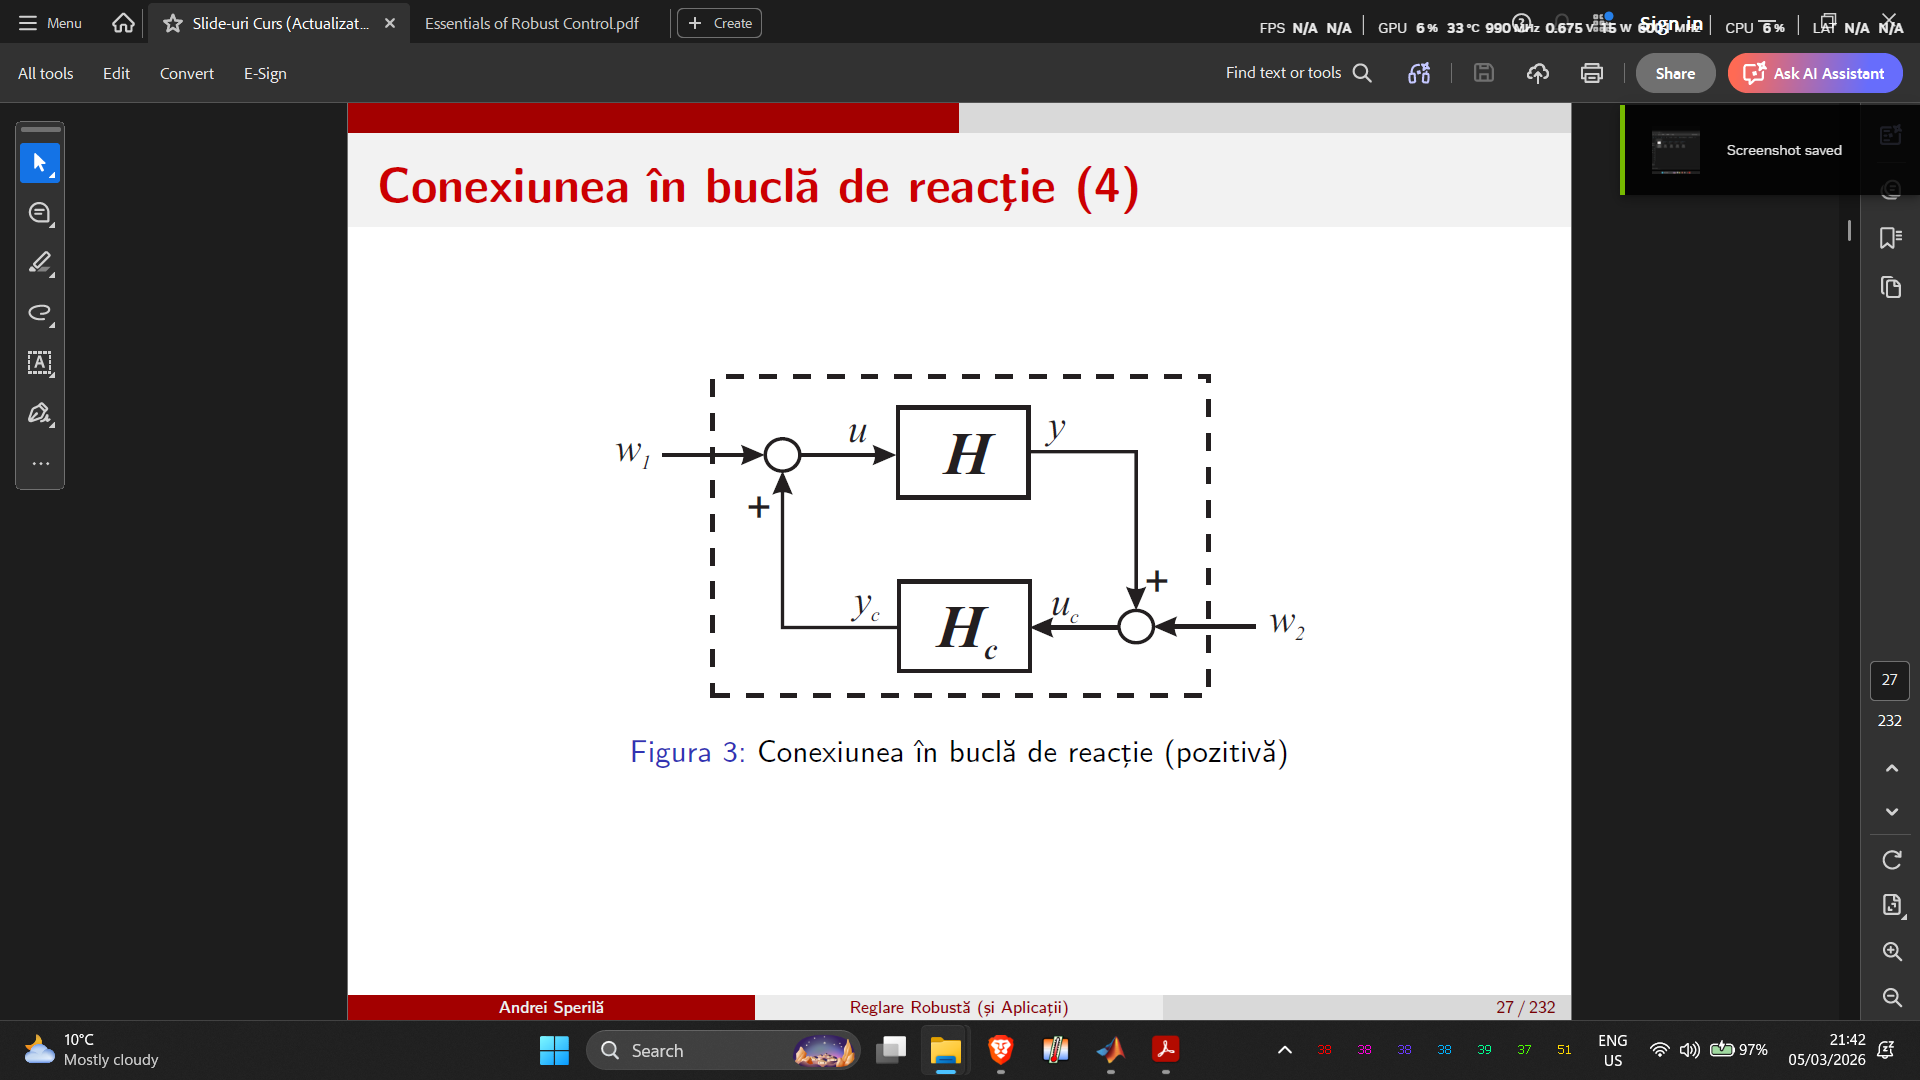.

Daca avem reactie negativa, putem adauga un bloc cu constanta -1 la $G_2$, adica schimbam semnul

clear
close all
clc

s = tf('s');


Aici definim un G

G = 1 / (s + 1) * ones(2,2)


G =
 
  From input 1 to output...
         1
   1:  -----
       s + 1
 
         1
   2:  -----
       s + 1
 
  From input 2 to output...
         1
   1:  -----
       s + 1
 
         1
   2:  -----
       s + 1
 
Continuous-time transfer function.


Il scriem in spatiul starilor (state-space)

G_ss = ss(G)


G_ss =
 
  A = 
       x1  x2
   x1  -1   0
   x2   0  -1
 
  B = 
       u1  u2
   x1   2   0
   x2   0   2
 
  C = 
        x1   x2
   y1  0.5  0.5
   y2  0.5  0.5
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


% Ma uit la zerourile de invarianta
tzero(G_ss.A, G_ss.B, G_ss.C, G_ss.D)


ans =

  0×1 empty double column vector



Observam ca nu avem zerouri invariante, adica nu pica rangul reprezentarii pe stare

rank([G_ss.A, G_ss.B; ...
      G_ss.C, G_ss.D])

ans = 3

% se vede ca nu este minimal (rangul nu este 4)


Aici inlocuim pe D cu identitatea

G_ss.D = eye(2);

G_ss


G_ss =
 
  A = 
       x1  x2
   x1  -1   0
   x2   0  -1
 
  B = 
       u1  u2
   x1   2   0
   x2   0   2
 
  C = 
        x1   x2
   y1  0.5  0.5
   y2  0.5  0.5
 
  D = 
       u1  u2
   y1   1   0
   y2   0   1
 
Continuous-time state-space model.



G_min = ss(G_ss, 'min')


G_min =
 
  A = 
       x1
   x1  -1
 
  B = 
          u1     u2
   x1  1.414  1.414
 
  C = 
           x1
   y1  0.7071
   y2  0.7071
 
  D = 
       u1  u2
   y1   1   0
   y2   0   1
 
Continuous-time state-space model.



tf(G_min)


ans =
 
  From input 1 to output...
       s + 2
   1:  -----
       s + 1
 
         1
   2:  -----
       s + 1
 
  From input 2 to output...
         1
   1:  -----
       s + 1
 
       s + 2
   2:  -----
       s + 1
 
Continuous-time transfer function.



tzero(G_min)

ans = -3.0000

Mai ok decat $\textrm{inv}\left(G\_\min \right)$

G_inv = eye(size(G_min)) / G_min


G_inv =
 
  A = 
           x1      x2      x3
   x1      -1   1.414   1.414
   x2  0.7071       1       0
   x3  0.7071       0       1
 
  B = 
       u1  u2
   x1   0   0
   x2  -1   0
   x3   0  -1
 
  C = 
       x1  x2  x3
   y1   0   1   0
   y2   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
  E = 
       x1  x2  x3
   x1   1   0   0
   x2   0   0   0
   x3   0   0   0
 
Continuous-time state-space model.



tf(G_inv)


ans =
 
  From input 1 to output...
       s + 2
   1:  -----
       s + 3
 
        -1
   2:  -----
       s + 3
 
  From input 2 to output...
        -1
   1:  -----
       s + 3
 
       s + 2
   2:  -----
       s + 3
 
Continuous-time transfer function.



tzero(G_inv)

ans = -1.0000

Prin transpunere, se poate vedea dualitatea

G_inv'


ans =
 
  A = 
            x1       x2       x3
   x1        1  -0.7071  -0.7071
   x2   -1.414       -1        0
   x3   -1.414        0       -1
 
  B = 
       u1  u2
   x1   0   0
   x2  -1   0
   x3   0  -1
 
  C = 
       x1  x2  x3
   y1   0  -1   0
   y2   0   0  -1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
  E = 
       x1  x2  x3
   x1   1   0   0
   x2   0   0   0
   x3   0   0   0
 
Continuous-time state-space model.


% Daca G este rationala, G' este conjugata

Aici vedem conjugatul

help conj

 conj - Complex conjugate
    This MATLAB function returns the complex conjugate of each element in Z.

    Syntax
      Zc = conj(Z)

    Input Arguments
      Z - Input array
        scalar | vector | matrix | multidimensional array

    Examples
      Find Complex Conjugate of Complex Number
      Find Complex Conjugate of Complex Values in Matrix

    See also  i ,  j , imag, real, ctranspose, co


conj(G_min)


ans =
 
  A = 
       x1
   x1  -1
 
  B = 
          u1     u2
   x1  1.414  1.414
 
  C = 
           x1
   y1  0.7071
   y2  0.7071
 
  D = 
       u1  u2
   y1   1   0
   y2   0   1
 
Continuous-time state-space model.


% Dualul

T = ss(randn(3), randn(3,2), randn(2,3), zeros(2,2))


T =
 
  A = 
            x1       x2       x3
   x1   0.5377   0.8622  -0.4336
   x2    1.834   0.3188   0.3426
   x3   -2.259   -1.308    3.578
 
  B = 
             u1        u2
   x1     2.769    0.7254
   x2     -1.35  -0.06305
   x3     3.035    0.7147
 
  C = 
            x1       x2       x3
   y1   -0.205     1.49    1.417
   y2  -0.1241    1.409   0.6715
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


Conexiunea serie

Eps = series(T, G_ss)


Eps =
 
  A = 
            x1       x2       x3       x4       x5
   x1       -1        0  -0.4099    2.979    2.834
   x2        0       -1  -0.2483    2.818    1.343
   x3        0        0   0.5377   0.8622  -0.4336
   x4        0        0    1.834   0.3188   0.3426
   x5        0        0   -2.259   -1.308    3.578
 
  B = 
             u1        u2
   x1         0         0
   x2         0         0
   x3     2.769    0.7254
   x4     -1.35  -0.06305
   x5     3.035    0.7147
 
  C = 
            x1       x2       x3       x4       x5
   y1      0.5      0.5   -0.205     1.49    1.417
   y2      0.5      0.5  -0.1241    1.409   0.6715
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


% sau
Eps1 = G_ss * T


Eps1 =
 
  A = 
            x1       x2       x3       x4       x5
   x1       -1        0  -0.4099    2.979    2.834
   x2        0       -1  -0.2483    2.818    1.343
   x3        0        0   0.5377   0.8622  -0.4336
   x4        0        0    1.834   0.3188   0.3426
   x5        0        0   -2.259   -1.308    3.578
 
  B = 
             u1        u2
   x1         0         0
   x2         0         0
   x3     2.769    0.7254
   x4     -1.35  -0.06305
   x5     3.035    0.7147
 
  C = 
            x1       x2       x3       x4       x5
   y1      0.5      0.5   -0.205     1.49    1.417
   y2      0.5      0.5  -0.1241    1.409   0.6715
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


% Pentru ca 2 realizari sunt diferite, rationala nu este la fel

Conexiune paralel

Par = G_ss + T


Par =
 
  A = 
            x1       x2       x3       x4       x5
   x1       -1        0        0        0        0
   x2        0       -1        0        0        0
   x3        0        0   0.5377   0.8622  -0.4336
   x4        0        0    1.834   0.3188   0.3426
   x5        0        0   -2.259   -1.308    3.578
 
  B = 
             u1        u2
   x1         2         0
   x2         0         2
   x3     2.769    0.7254
   x4     -1.35  -0.06305
   x5     3.035    0.7147
 
  C = 
            x1       x2       x3       x4       x5
   y1      0.5      0.5   -0.205     1.49    1.417
   y2      0.5      0.5  -0.1241    1.409   0.6715
 
  D = 
       u1  u2
   y1   1   0
   y2   0   1
 
Continuous-time state-space model.


Conexiune in bucla de reactie

s_cl = feedback(G, -T)


s_cl =
 
  A = 
            x1       x2       x3       x4       x5
   x1       -1        0  -0.4099    2.979    2.834
   x2        0       -1  -0.2483    2.818    1.343
   x3    1.747    1.747   0.5377   0.8622  -0.4336
   x4  -0.7065  -0.7065    1.834   0.3188   0.3426
   x5    1.875    1.875   -2.259   -1.308    3.578
 
  B = 
       u1  u2
   x1   2   0
   x2   0   2
   x3   0   0
   x4   0   0
   x5   0   0
 
  C = 
        x1   x2   x3   x4   x5
   y1  0.5  0.5    0    0    0
   y2  0.5  0.5    0    0    0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


% Sau feedback(G, T, 1). Tot aia


## Transfromari Liniar Fractionare (TLF-uri)

Haos matlab

Aceste coexiuni sunt o extensie la clasa **matricilor de transfer rationale** a transformarii liniar fractionare din cazul scalar

$f\left(\lambda \right)=\frac{a+b\lambda }{c+d\lambda }\left(\textrm{Transformare}\;\textrm{Mobius}\right)$, unde a,b,c,d sunt constante reale

### Fie 2 sisteme $\left\lbrace \begin{array}{l}
T\left(s\right)=\left\lbrack \begin{array}{ccc}
A & B_1  & B_2 \\
C_1  & D_{11}  & D_{12} \\
C_2  & D_{21}  & D_{22} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
T_{11}  & T_{12} \\
T_{21}  & T_{22} 
\end{array}\right\rbrack \\
K\left(s\right)=\left\lbrack \begin{array}{cc}
A_K  & B_K \\
C_K  & D_K 
\end{array}\right\rbrack 
\end{array}\right.$

Daca $\left\lbrace \begin{array}{l}
\textrm{numar}\;\textrm{iesiri}\;\textrm{ale}\;\textrm{lui}\;T_{22} =\textrm{numar}\;\textrm{intrati}\;\textrm{ale}\;\textrm{lui}\;K\\
\textrm{numar}\;\textrm{iesiri}\;\textrm{alu}\;\textrm{lui}\;K=\textrm{numar}\;\textrm{intrari}\;\textrm{ale}\;\textrm{lui}\;T_{22} 
\end{array}\right.$ se defineste **Transformarea Liniar Fractionara INFERIOARA (TLFi)** a lui $T\;\textrm{cu}\;K$ca fiind sistemul obtinut punand$\left\lbrace \begin{array}{l}
u_2 =y_K \\
u_K =y_2 
\end{array}\right.$

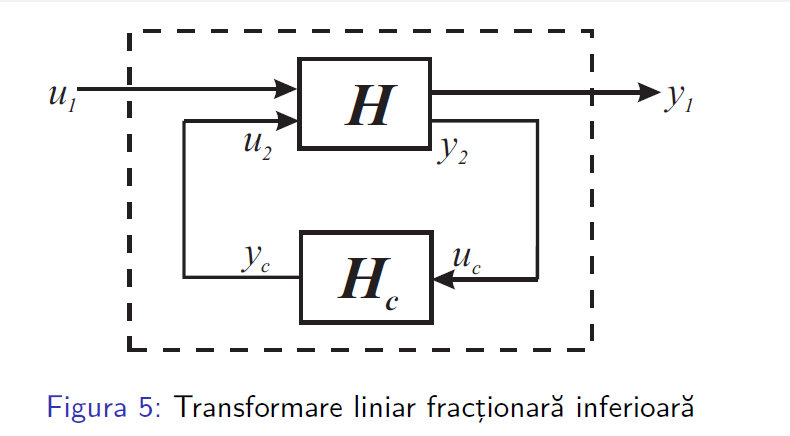


$$\textrm{TLFI}\left(T,K\right)=T_{11} +T_{12} {K\left(I-T_{22} K\right)}^{-1} T_{21}$$


Trebuie ca ${\left(I-T_{22} K\right)}^{-1}$ sa existe. De asemenea, pentru buna definire avem nevoie ca $\left\lbrack \begin{array}{cc}
I & -D_c \\
-D_{22}  & I
\end{array}\right\rbrack$ sa fie inversabila

Daca $\left\lbrace \begin{array}{l}
\textrm{numar}\;\textrm{iesiri}\;\textrm{ale}\;\textrm{lui}\;T_{11} =\textrm{numar}\;\textrm{intrati}\;\textrm{ale}\;\textrm{lui}\;K\\
\textrm{numar}\;\textrm{iesiri}\;\textrm{alu}\;\textrm{lui}\;K=\textrm{numar}\;\textrm{intrari}\;\textrm{ale}\;\textrm{lui}\;T_{11} 
\end{array}\right.$ se defineste **Transformarea Liniar Fractionara SUPERIOARA (TLFs)** a lui $T\;\textrm{cu}\;K$ca fiind sistemul obtinut punand$\left\lbrace \begin{array}{l}
u_1 =y_K \\
u_K =y_1 
\end{array}\right.$

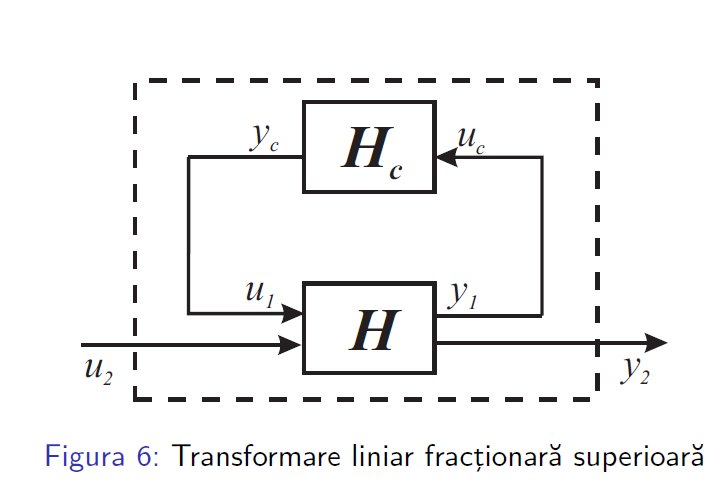


$$\textrm{TLFS}\left(T,K\right)=T_{22} +T_{21} {K\left(I-T_{11} K\right)}^{-2} T_{12}$$


Trebuie ca ${\left(I-T_{11} K\right)}^{-2}$ sa existe. De semenea, pentru buna definire avem nevoie de $\left\lbrack \begin{array}{cc}
I & -D_{11} \\
-D_K  & I
\end{array}\right\rbrack$ sa fie inversabila

clear
close all
clc

s = tf('s');

G = 1 / (s + 1) * ones(2,2)


G =
 
  From input 1 to output...
         1
   1:  -----
       s + 1
 
         1
   2:  -----
       s + 1
 
  From input 2 to output...
         1
   1:  -----
       s + 1
 
         1
   2:  -----
       s + 1
 
Continuous-time transfer function.


G_ss = ss(G)


G_ss =
 
  A = 
       x1  x2
   x1  -1   0
   x2   0  -1
 
  B = 
       u1  u2
   x1   2   0
   x2   0   2
 
  C = 
        x1   x2
   y1  0.5  0.5
   y2  0.5  0.5
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


G_ss.D = eye(2);
G_ss


G_ss =
 
  A = 
       x1  x2
   x1  -1   0
   x2   0  -1
 
  B = 
       u1  u2
   x1   2   0
   x2   0   2
 
  C = 
        x1   x2
   y1  0.5  0.5
   y2  0.5  0.5
 
  D = 
       u1  u2
   y1   1   0
   y2   0   1
 
Continuous-time state-space model.



H = 2 / (s + 3);

help lft

 lft - Generalized feedback interconnection of two models (Redheffer star product)
    This MATLAB function forms the star product or linear fractional
    transformation (LFT) of two model objects or model arrays.

    Syntax
      lft
      sys = lft(sys1,sys2,nu,ny)

    See also connect, feedback

    Introduced in Control System Toolbox before R2006a
    Documentation for lft
    Other uses of lft



Aici definim **TLFi**

lft(G_ss, H)


ans =
 
  A = 
       x1  x2  x3
   x1  -1   0   0
   x2   0  -1   2
   x3   1   1  -1
 
  B = 
       u1
   x1   2
   x2   0
   x3   0
 
  C = 
        x1   x2   x3
   y1  0.5  0.5    0
 
  D = 
       u1
   y1   1
 
Continuous-time state-space model.


% Primul este ala de sus, cel de al doilea jos

Asta este $\textrm{TLFI}\left(T,K\right)$

P_i = G_ss(1,1) + G_ss(1,2) * feedback(H,-G_ss(2,2)) * G_ss(2,1)


P_i =
 
  A = 
       x1  x2  x3  x4  x5  x6  x7  x8  x9
   x1  -1   0   0   0   0   0   0   0   0
   x2   0  -1   0   0   0   0   0   0   0
   x3   0   0  -1   0   0   0   0   0   0
   x4   0   0   0  -1   2   0   0   0   0
   x5   0   0   0   0  -1   1   1   1   1
   x6   0   0   0   0   0  -1   0   0   0
   x7   0   0   0   0   2   0  -1   0   0
   x8   0   0   0   0   0   0   0  -1   0
   x9   0   0   0   0   0   0   0   0  -1
 
  B = 
       u1
   x1   2
   x2   0
   x3   0
   x4   0
   x5   0
   x6   0
   x7   0
   x8   2
   x9   0
 
  C = 
        x1   x2   x3   x4   x5   x6   x7   x8   x9
   y1  0.5  0.5  0.5  0.5    0    0    0    0    0
 
  D = 
       u1
   y1   1
 
Continuous-time state-space model.



norm(P_i - lft(G_ss, H), 'inf')

ans = 5.5511e-17


ss(P_i - lft(G_ss, H), 'min')


ans =
 
  D = 
       u1
   y1   0
 
Static gain.


O alta metoda ce a calcula inversa unei matrici

G_inv_2 = feedback(eye(2), eye(2) - G_ss, 1)


G_inv_2 =
 
  A = 
       x1  x2
   x1  -2  -1
   x2  -1  -2
 
  B = 
       u1  u2
   x1   2   0
   x2   0   2
 
  C = 
         x1    x2
   y1  -0.5  -0.5
   y2  -0.5  -0.5
 
  D = 
       u1  u2
   y1   1   0
   y2   0   1
 
Continuous-time state-space model.


**TLFS** = TFLI pe invers

lft(H, G_ss)


ans =
 
  A = 
       x1  x2  x3
   x1  -1   1   1
   x2   2  -1   0
   x3   0   0  -1
 
  B = 
       u1
   x1   0
   x2   0
   x3   2
 
  C = 
        x1   x2   x3
   y1    0  0.5  0.5
 
  D = 
       u1
   y1   1
 
Continuous-time state-space model.


Acum calculam $\textrm{TLFS}\;\left(T,K\right)$

P_u = G_ss(2,2) + G_ss(2,1) * feedback(H, -G_ss(1,1)) * G_ss(1,2)


P_u =
 
  A = 
       x1  x2  x3  x4  x5  x6  x7  x8  x9
   x1  -1   0   0   0   0   0   0   0   0
   x2   0  -1   0   0   0   0   0   0   0
   x3   0   0  -1   0   2   0   0   0   0
   x4   0   0   0  -1   0   0   0   0   0
   x5   0   0   0   0  -1   1   1   1   1
   x6   0   0   0   0   2  -1   0   0   0
   x7   0   0   0   0   0   0  -1   0   0
   x8   0   0   0   0   0   0   0  -1   0
   x9   0   0   0   0   0   0   0   0  -1
 
  B = 
       u1
   x1   0
   x2   2
   x3   0
   x4   0
   x5   0
   x6   0
   x7   0
   x8   0
   x9   2
 
  C = 
        x1   x2   x3   x4   x5   x6   x7   x8   x9
   y1  0.5  0.5  0.5  0.5    0    0    0    0    0
 
  D = 
       u1
   y1   1
 
Continuous-time state-space model.



norm(P_u - lft(G_ss, H), 'inf')

ans = 5.5511e-17


ss(P_u - lft(G_ss, H), 'min')


ans =
 
  D = 
       u1
   y1   0
 
Static gain.


## Norme

Vom folosi 2 norme cunoscute de noi: $\left\lbrace \begin{array}{l}
{\mathcal{L}}_{\infty } \\
{\mathcal{L}}_2 
\end{array}\right.$. Mai intai incepem cu norma infinit.

Pentru un $G\left(s\right)\in {\mathbb{R}\left(s\right)}^{\textrm{pxm}} \to ||G||_{\infty } =\left\lbrace \begin{array}{l}
\textrm{SISO}:\sup_{w\in \mathbb{R}} |G\left(\textrm{jw}\right)|\\
\textrm{MIMO}:\sup_{w\in \mathbb{R}} \bar{\sigma} \left(G\left(\textrm{jw}\right)\right)
\end{array}\right.$. In cazul MIMO, $\bar{\sigma}$ este valoarea maxima singulara a matricii de transfer $G\left(s\right)$. Noi in cazul MIMO **nu avem valori proprii, cu functii proprii si practic ne uitam la fiecare functie si luam doar maximul.**

Facem SVD pe $G\left(s\right)$ si ne uitam la $\Sigma$ care ce da $\bar{\sigma}$

clear
close all
clc

s = tf('s');

G = 1 / (s + 1) * ones(2,2)


G =
 
  From input 1 to output...
         1
   1:  -----
       s + 1
 
         1
   2:  -----
       s + 1
 
  From input 2 to output...
         1
   1:  -----
       s + 1
 
         1
   2:  -----
       s + 1
 
Continuous-time transfer function.


G_ss = ss(G)


G_ss =
 
  A = 
       x1  x2
   x1  -1   0
   x2   0  -1
 
  B = 
       u1  u2
   x1   2   0
   x2   0   2
 
  C = 
        x1   x2
   y1  0.5  0.5
   y2  0.5  0.5
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


G_ss.D = eye(2);

Aici arat cum se foloseset SVD si ce face aproximativ sigma(G_ss)

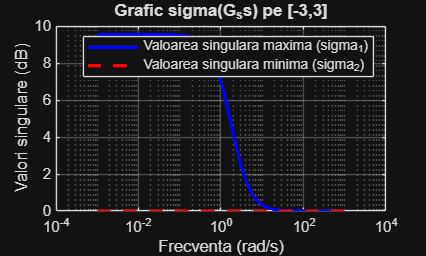

% Setez frecventa dorita
% Aici vreau sa iau din -3 in 3 10,000 puncte
w = logspace(-3, 3, 1e4);

% Aici vad cum raspunde sistemul la anumite frecvente.
% G_freq este matrice 3D
G_freq = freqresp(G_ss, w);

% Pentru simplitate, predefinesc sigmav ca fiind plin de 0
sigmav = zeros(2, length(w));

% Parcurg intervalul [-3,3] si aplic la fiecare frecventa svd
for i = 1:length(w)
    % Extrage matricea complexa statica 2x2 pentru frecventa curenta
    G_omega = G_freq(:, :, i);
    
    % Calculare SVD
    % Matlab, din ce vad, sorteaza automat valorile singulare in E de la
    % cel mai mare la cel mai mic
    [U, E, V] = svd(G_omega);
    
    % Acum extragem valorile singulare din S
    % Primul element este valoarea singulare maxima
    sigmav(:, i) = diag(E);
end

% Acum vizualiazam
figure;
semilogx(w, 20*log10(sigmav(1, :)), 'b', 'LineWidth', 2);
hold on;
semilogx(w, 20*log10(sigmav(2, :)), 'r--', 'LineWidth', 2);
grid on;
xlabel('Frecventa (rad/s)');
ylabel('Valori singulare (dB)');
title('Grafic sigma(G_ss) pe [-3,3]');
legend('Valoarea singulara maxima (sigma_1)', ...
    'Valoarea singulara minima (sigma_2)');


% Acum cautam norma infinit, adica maximul maxim de pe graficul desenat
% Noi ne uitam la valorile normale, nu pe scara logaritmica
H_inf_calculated = max(sigmav(1, :))

H_inf_calculated = 3.0000


% Ne verificam cu matlab
H_inf_builtin = norm(G_ss, 'inf')

H_inf_builtin = 3.0000

Daca $||G||_{\infty } <\infty \Leftrightarrow$G nu are pol pe axa imaginara

T = ss(randn(3), randn(3,2), randn(2,3), eye(2,2))


T =
 
  A = 
            x1       x2       x3
   x1   0.5377   0.8622  -0.4336
   x2    1.834   0.3188   0.3426
   x3   -2.259   -1.308    3.578
 
  B = 
             u1        u2
   x1     2.769    0.7254
   x2     -1.35  -0.06305
   x3     3.035    0.7147
 
  C = 
            x1       x2       x3
   y1   -0.205     1.49    1.417
   y2  -0.1241    1.409   0.6715
 
  D = 
       u1  u2
   y1   1   0
   y2   0   1
 
Continuous-time state-space model.



help norm

 norm - Vector and matrix norms
    This MATLAB function returns the Euclidean norm of vector v.

    Syntax
      n = norm(v)
      n = norm(v,p)

      n = norm(X)
      n = norm(X,p)
      n = norm(X,"fro")

    Input Arguments
      v - Input vector
        vector
      X - Input array
        matrix | array
      p - Norm type
        2 (default) | positive real scalar | Inf | -Inf

    Output Arguments
      n - Norm value
        scalar

    Examples
      Vector Magnitude
      


norm(G_ss, 'inf')

ans = 3.0000


help sigma

 sigma - Singular values of frequency response of dynamic system
    This MATLAB function returns the singular values sv of the frequency
    response of dynamic system model sys at each frequency in the vector
    wout.

    Syntax
      [sv,wout] = sigma(sys)
      [sv,wout] = sigma(sys,w)
      sv = sigma(sys,w,type)

      sigma(___)

    Input Arguments
      sys - Dynamic system
        dynamic system model | model array
      w - Frequencies
        {wmin,wmax} | vector | []
      type - Type of modified singu

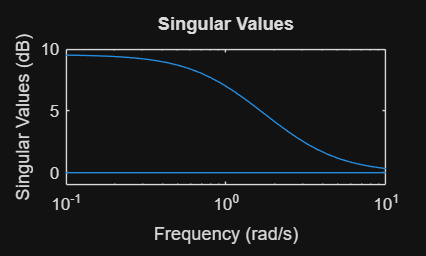


figure
sigma(G_ss)


hinfnorm(G_ss)

ans = 3.0000


norm (G_ss, 'inf')

ans = 3.0000

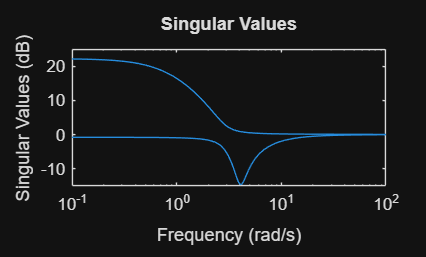


figure
sigma(T)


roots(tf(T).den{1})

ans =     3.8142
    1.4678
   -0.8472



norm(T, 'inf')

ans = 12.9101

$G\in \mathcal{R}{\mathcal{L}}_{\infty } {\left(s\right)}^{\textrm{pxm}} \Leftrightarrow G$ este proprie si nu are poli pe axa imaginara

Fie $\gamma >0,G\left(s\right)=\left\lbrack \begin{array}{cc}
A & B\\
C & D
\end{array}\right\rbrack \;\textrm{cu}\;\Lambda \left(A\right)\bigcap {\mathbb{C}}_0 =\left\lbrace \O \right\rbrace \;\textrm{si}$

$\left\lbrace \begin{array}{l}
R_{\gamma } =\left\lbrack \begin{array}{cc}
A+{\textrm{BR}}_{\gamma }^{-1} D^T C & {\textrm{BR}}_{\gamma }^{-1} B^T \\
-C^T \left(I+{\textrm{DR}}_{\gamma }^{-1} D^T \right)C & -{\left(A+{\textrm{BR}}_{\gamma }^{-1} D^T C\right)}^T 
\end{array}\right\rbrack \\
R_{\gamma } =\gamma^2 I-D^T D
\end{array}\right.$ avem $||G||_{\infty } <\gamma \Leftrightarrow R_{\gamma } >0\;\textrm{si}\;\Lambda \left(H_{\gamma } \right)\bigcap {\mathbb{C}}_0 =\O$

Acest rezultat are loc in cazul generic al sistemeor MIMO

**Matricea **$H_{\gamma } \in {\mathbb{R}}^{2\textrm{nx2n}}$** este o matrice de tip Hamilton.**

#### Ce este o matrice Hamilton?

O matrice hamilton este o matrice care are simetrie a spectrului in raport cu axa imaginara, adica daca avem $\lambda ,\textrm{avem}\;\textrm{si}\;\bar{\lambda} ,-\lambda \;\textrm{si}-\bar{\lambda}$. Mai exact, satisface ${\left({\textrm{JH}}_{\gamma } \right)}^T ={\textrm{JH}}_{\gamma } ,\textrm{unde}\;J=\left\lbrack \begin{array}{cc}
0_n  & I_n \\
-I_n  & 0_n 
\end{array}\right\rbrack$ si se numeste matrice antisimetrica

## Lema de reala marginire

Nu ai cum algotritmic sa faci in numar finit de pasi sa calculezi norma infinit

H_gam = [G_ss.A + G_ss.B * G_ss.D' * G_ss.C / 3, G_ss.B * eye(2) * G_ss.B' / 3;
    -G_ss.C' * (eye(2) + G_ss.D * eye(2) * G_ss.D' / 3) * G_ss.C, -(G_ss.A + G_ss.B * G_ss.D' * G_ss.C / 3)']

H_gam =    -0.6667    0.3333    1.3333         0
    0.3333   -0.6667         0    1.3333
   -0.6667   -0.6667    0.6667   -0.3333
   -0.6667   -0.6667   -0.3333    0.6667



eig(H_gam)

ans =   -1.0000 + 0.0000i
  -0.0000 + 1.2910i
  -0.0000 - 1.2910i
   1.0000 + 0.0000i


## Norma 2

Pentru **Matricea de Transfer (cazul MIMO)** definim $||G||_2 :={\left\lbrace \frac{1}{2\pi }\int_{-\infty }^{\infty } \textrm{tr}\left\lbrack G\tilde{} \left(\textrm{jw}\right)G\left(\textrm{jw}\right)\right\rbrack \textrm{dw}\right\rbrace }^{\frac{1}{2}}$ care se numeste ${\mathcal{L}}_2$


$$||G||_2 <\infty \Leftrightarrow G\in \mathcal{R}{\mathcal{L}}_2 {\left(s\right)}^{\textrm{pxm}} \Leftrightarrow \left\lbrace \begin{array}{l}
G\left(s\right)\;\textrm{nu}\;\textrm{are}\;\textrm{poli}\;\textrm{pe}\;{\mathbb{C}}_0 \\
G\left(\infty \right)=0,\textrm{adica}\;\textrm{este}\;\textrm{strict}\;\textrm{proprie}
\end{array}\right.$$


S-ar putea rezolva norma 2 folosind **Teoria Reziduurilor**, cel mai bine folosim unele formule pe stare (Lyapunov)

norm(1 / (s - 1), 2)

ans = Inf

Asta calculeaza H_2, nu L_2

help stabsep

--- help for DynamicSystem/stabsep ---

 DynamicSystem/stabsep - Stable-unstable decomposition
    This MATLAB function decomposes the linear time-invariant (LTI) model G
    into its stable and unstable parts.

    Syntax
      [G1,G2] = stabsep(G)
      [G1,G2] = stabsep(G,Offset)
      [G1,G2] = stabsep(G,___,Name=Value)
      [G1,G2,info] = stabsep(___)

    Input Arguments
      G - Dynamic system to decompose
        numeric LTI model
      Offset - Offset for stable/unstable boundary
        0 (default) | scalar

    Name-Value Arguments
      


G_ss = ss(G)


G_ss =
 
  A = 
       x1  x2
   x1  -1   0
   x2   0  -1
 
  B = 
       u1  u2
   x1   2   0
   x2   0   2
 
  C = 
        x1   x2
   y1  0.5  0.5
   y2  0.5  0.5
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



norm(G_ss, 2)

ans = 1.4142

% aproximativ sqrt(2)

Presupunem ca sistemul este luat aleator si este reprezentat intr-o stare minimala. Norma lui 2 este finita $\Leftrightarrow \left\lbrace \begin{array}{l}
D=0\\
A\;\textrm{este}\;\textrm{dihotomica}
\end{array}\right.$. In acest sens, sistemul se poate aduce la forma $G\left(s\right)=G_s \left(s\right)+G_a \left(s\right),\textrm{unde}\;\left\lbrace \begin{array}{l}
G_s \left(s\right)\;\textrm{are}\;\textrm{polii}\;\textrm{in}\;{\mathbb{C}}_- \;\left(\textrm{este}\;\textrm{stabil}\right)\\
G_a \left(s\right)\;\textrm{are}\;\textrm{polii}\;\textrm{in}\;{\mathbb{C}}_+ \left(\textrm{este}\;\textrm{antistabil}\right)
\end{array}\right.$. Atunci are loc rezultatul: $||G||_2^2 =||G_s ||_2^2 +||G_a ||_2^2$. 

 O mica observatie: Stim ca $G_s \;\textrm{si}\;G_a$ sunt ortogonale si ca $||\tilde{G} ||_2 =||G||_2$. In acest sens, daca $G_a$ este antistabil, asta inseamna ca $\tilde{G_a \left(s\right)} =G_a^T \left(-s\right)$ care este stabil. Asadar, putem rescrie egalitatea in felul irmator: $||G||_2^2 =||G_s ||_2^2 +||\tilde{G_a } ||_2^2$ si este suma de 2 stabile

#### Acum trebuie calculate cele 2 norme. Cum facem asta? Uite aici:

**Pentru A stabil, norma 2 se calculeaza: **$||G||_2 ={\left\lbrack \textrm{tr}\left(B^T \textrm{QB}\right)\right\rbrack }^{\frac{1}{2}} ={\left\lbrack \textrm{tr}\left({\textrm{CPC}}^T \right)\right\rbrack }^{\frac{1}{2}} ,\textrm{unde}\;P\;\textrm{si}\;Q\;\textrm{sunt}\;\textrm{solutiile}\;\textrm{unice}\;\textrm{ale}\;\textrm{ecuatiilor}\;\textrm{Lyapunov}$


$$\left\lbrace \begin{array}{l}
\textrm{AP}+{\textrm{PA}}^T +{\textrm{BB}}^T =0\\
A^T Q+\textrm{QA}+C^T C=0
\end{array}\right.$$


**Pentru A instabil, norma 2 se calculeaza: **


$$||G||_2 ={\left\lbrack \textrm{tr}\left(B^T \hat{Q} B\right)\right\rbrack }^{\frac{1}{2}} ={\left\lbrack \textrm{tr}\left({C\hat{P} C}^T \right)\right\rbrack }^{\frac{1}{2}} ,\textrm{unde}\;\hat{P} \;\textrm{si}\;\hat{Q} \;\textrm{sunt}\;\textrm{solutiile}\;\textrm{unice}\;\textrm{ale}\;\textrm{ecuatiilor}\;\textrm{Lyapunov}$$


$\left\lbrace \begin{array}{l}
A\hat{P} +{\hat{P} A}^T -{\textrm{BB}}^T =0\\
A^T \hat{Q} +\hat{Q} A-C^T C=0
\end{array}\right.$, unde tr(A) reprezinta suma elementelor de pe diagonala principala

help lyap

 lyap - Solve continuous-time Lyapunov equation
    Use lyap to solve the special and general forms of the Lyapunov
    equation.

    Syntax
      X = lyap(A,Q)
      X = lyap(A,B,C)
      X = lyap(A,Q,[],E)

    Input Arguments
      A - Input matrices
        matrices
      Q - Input matrices
        matrices
      B - Input matrices
        matrices
      C - Input matrices
        matrices
      E - Input matrices
        matrices

    Output Arguments
      


P = lyap(G_ss.A, G_ss.B * G_ss.B')

P =      2     0
     0     2



Q = lyap(G_ss.A', G_ss.C' * G_ss.C)

Q =     0.2500    0.2500
    0.2500    0.2500



G_ss.A * P + P * G_ss.A' + G_ss.B * G_ss.B'

ans =      0     0
     0     0



G_ss.A' * Q + Q * G_ss.A + G_ss.C' * G_ss.C

ans =      0     0
     0     0



rez = sqrt(trace(G_ss.B' * Q * G_ss.B))

rez = 1.4142


rez1 = sqrt(trace(G_ss.C * P * G_ss.C'))

rez1 = 1.4142


T = T + T' + eye(2)


T =
 
  A = 
            x1       x2       x3       x4       x5       x6
   x1   0.5377   0.8622  -0.4336        0        0        0
   x2    1.834   0.3188   0.3426        0        0        0
   x3   -2.259   -1.308    3.578        0        0        0
   x4        0        0        0  -0.5377   -1.834    2.259
   x5        0        0        0  -0.8622  -0.3188    1.308
   x6        0        0        0   0.4336  -0.3426   -3.578
 
  B = 
             u1        u2
   x1     2.769    0.7254
   x2     -1.35  -0.06305
   x3     3.035    0.7147
   x4     0.205    0.1241
   x5     -1.49    -1.409
   x6    -1.417   -0.6715
 
  C = 
             x1        x2        x3        x4        x5        x6
   y1    -0.205      1.49     1.417     2.769     -1.35     3.035
   y2   -0.1241     1.409    0.6715    0.7254  -0.06305    0.7147
 
  D = 
       u1  u2
   y1   3   0
   y2   0   3
 
Continuous-time state-space model.



eig(T)

ans =     3.8142
   -0.8472
    1.4678
    0.8472
   -1.4678
   -3.8142



help stabsep

--- help for DynamicSystem/stabsep ---

 DynamicSystem/stabsep - Stable-unstable decomposition
    This MATLAB function decomposes the linear time-invariant (LTI) model G
    into its stable and unstable parts.

    Syntax
      [G1,G2] = stabsep(G)
      [G1,G2] = stabsep(G,Offset)
      [G1,G2] = stabsep(G,___,Name=Value)
      [G1,G2,info] = stabsep(___)

    Input Arguments
      G - Dynamic system to decompose
        numeric LTI model
      Offset - Offset for stable/unstable boundary
        0 (default) | scalar

    Name-Value Arguments
      


[T_st, T_a] = stabsep(T)


T_st =
 
  A = 
            x1       x2       x3
   x1  -0.8472        0        0
   x2        0   -1.468    1.403
   x3        0        0   -3.814
 
  B = 
            u1       u2
   x1    -2.56   -0.555
   x2   -1.143   -1.001
   x3   -1.448  -0.7118
 
  C = 
           x1      x2      x3
   y1   2.028   2.772   2.587
   y2   1.885   0.945  0.5635
 
  D = 
       u1  u2
   y1   3   0
   y2   0   3
 
Continuous-time state-space model.


Cateva surse:

[https://www.mathworks.com/help/robust/gs/interpretation-of-h-infinity-norm.html](https://www.mathworks.com/help/robust/gs/interpretation-of-h-infinity-norm.html)

[https://en.wikipedia.org/wiki/Hamiltonian_matrix](https://en.wikipedia.org/wiki/Hamiltonian_matrix)